# Lead compensator design using phase margins

This livescript is a brief manual in support of the app on how to do lead compensator design using frequency response methods, or specifically, by managing the phase margin and cross over frequency as viewed in a Bode diagram. The aim is to help users understand core principles and steps, after which they may prefer to use ***sisotool*** or other means to undertake designs on systems of their own choosing.

A logical supporting file is ***lead_design_with_bode.mlx*** which gives more comprehensive background and MATLAB source code alongside some examples. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help Control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Simple gain design using phase margin criteria

- The design and operation of the app

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

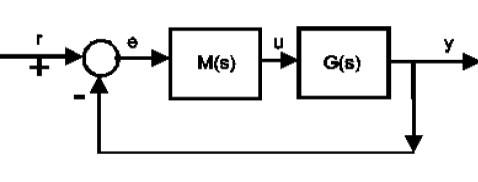

Readers should be familar with the file  **proportional_design_with_bode.mlx, proportional_design_phase_margin.mlapp *****and ***  ***lag_design_with_bode.mlx***  for background on performance specifications which underpin design and also because a similar process is a first step in a lead compensator design. For more information on this design and structure, see the file  ***lead_design_with_bode.mlx.***

%%%%%%  REMOVE COMMENTS TO RUN THE CODE AND OPEN THE RELEVANT TOOLBOX FILES
% proportional_design_with_bode
% proportional_design_phase_margin  
% lead_design_with_bode
% lag_design_with_bode
% lag_design_phase_margin

The closed-loop transfer function is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$ and the intention is to design the compensator M(s) to have the following stucture where*** K*** is a simple proportional.


$$M\left(s\right)=K\frac{s+a}{s+a\;r},\;\;\;\;\;\;r>1$$
      

Core properties of this compensator are that the low frequency gain is '***r***' times smaller than the high frequency gain and secondly, the system has positive phase in the regions near the corner frequencies: ***a, ar***. In order for make most use of the phase characteristic, the corner frequencies are chosen to bridge the desired gain cross over frequency $w_c$ and a scaling factor is added to make the 'gain' of the dynamic part unity at this frequency. Hence the lead takes the structure:  

$M\left(s\right)\;=\;K_p \;\left\lbrack \sqrt{\alpha }\;\left(\frac{s+\frac{w_c }{\sqrt{\alpha }}}{s+w_c \sqrt{\alpha }}\right)\right\rbrack$ ;                    $1\le \alpha \le 10$.

## 2. Lead compensator design steps

For slower and detailed explanations and more flexible code and examples, see the toolbox file:

%% UNCOMMENT TO OPEN THIS FILE
% lead_design_with_bode

Here we assume  the design is based on specifications:

- Desired PM

- Desired bandwidth (for simplicity of design the gain cross over frequency is used as a rough equivalent).

A simple lead design tackles these by dealing with the bandwidth first and then the PM second. To do this we undertake 2 separate mechanistic designs in order to meet the criteria one at a time. Subsequent steps need to be done in such a way as to preserve the already achieved criteria.

**Remark**: The app is primarily for illustrative purposes of the core design steps and thus only allows integer values of $\alpha$ and simple choices for other variables. If a user wants to meet criteria precisely (largely irrelevant for practical systems and control), they would need to do the relevant computations within MATLAB or sisotool, for example as shown in the file: ***lead_design_with_bode***.

### 2.1 Simple gain design to meet the bandwidth criteria

**Warning**: For this step, ensure the pole/zero ratio is one before beginning.

We want to design the gain $K_p$ of the compensator the ***M(s)*** so that we have a desirable gain cross over frequency $w_c$. The process is analaogous to the gain designs used for simple proportional design. In essence the gain $K_p$ is selected to meet the criteria:


$$\left|G\left(jw_c \right)\right|K_p =1$$


This can be done by an iteration of the  simple scaling on the gain plot and determining the implied cross over frequency visually as this aids insight into the process. However,  explicit computation is straightforward.

The app draws a vertical line (dotted green) at the target cross over frequency so the user can see when the gain plot (red line below in top figure because lead and proportional are the same in this picture) crosses zero dB at the correct frequency. The value of $K_p$ selected by the slider is also shown in the gain plot.

**Remark**: Section 3.2 offers an alternative route to performing this step which some will find more helpful.

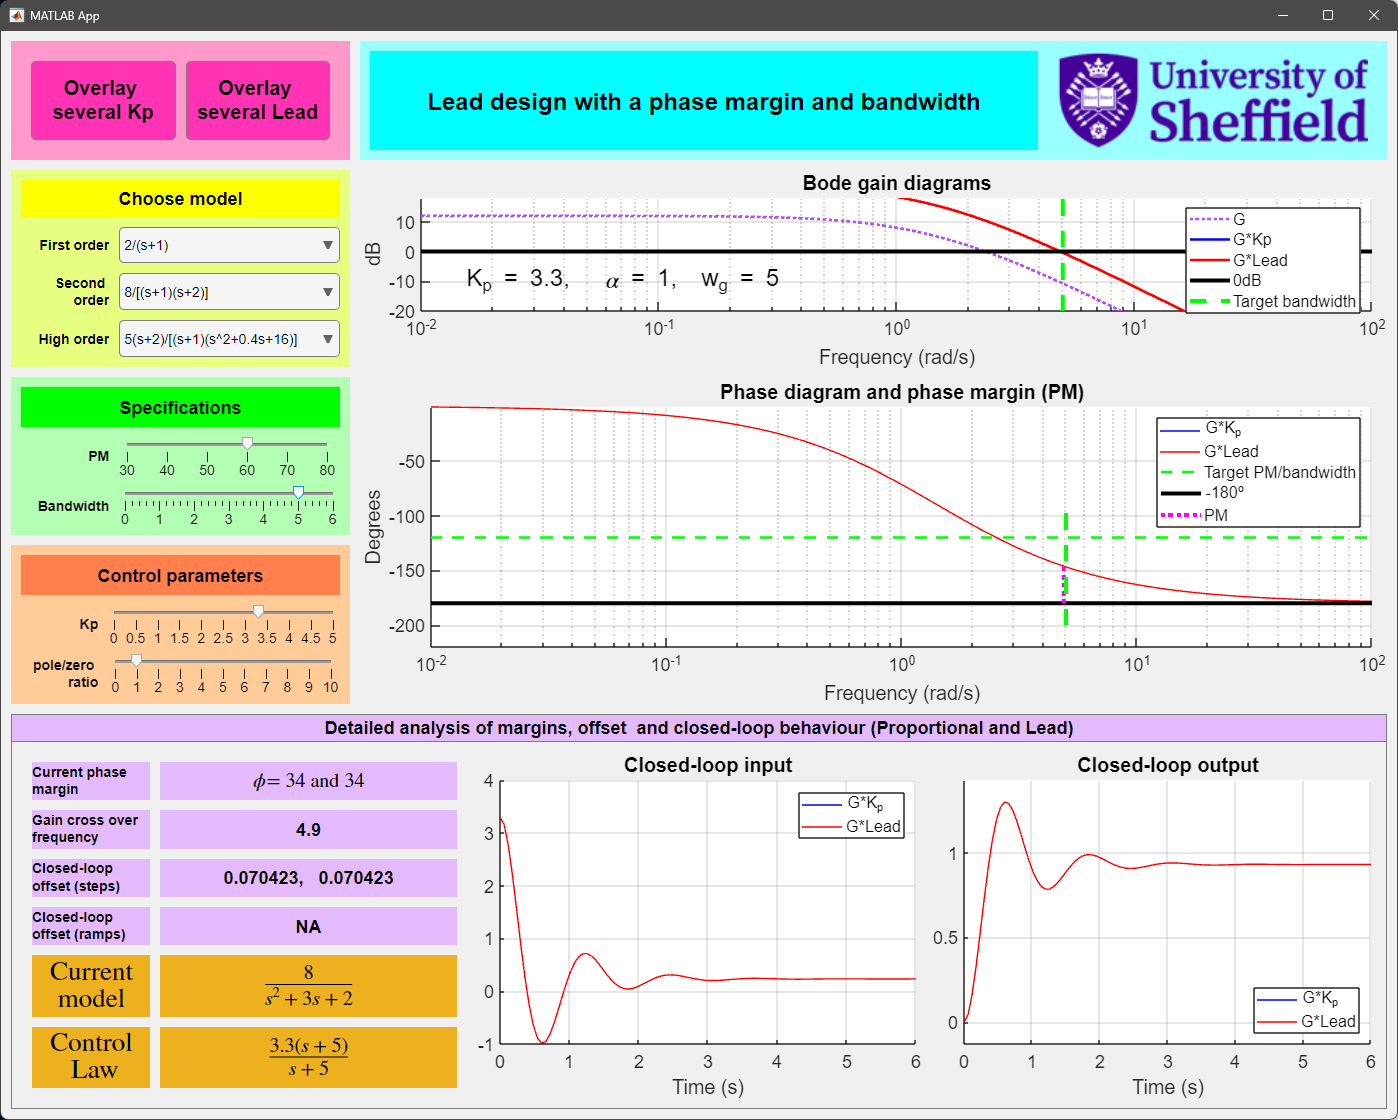

### 2.2 Adding the phase margin criteria

Having chosen the proportional gain, we add the lead component  $\;\left\lbrack \sqrt{\alpha }\;\left(\frac{s+\frac{w_c }{\sqrt{\alpha }}}{s+w_c \sqrt{\alpha }}\right)\right\rbrack$   to improve the phase margin. In the screen dump above it is clear that the current PM is only 34 and thus some positive phase rotation is needed (here the desired PM is set at 60 so a rotation of 26 is required).  It is known that the phase rotation $\phi$ provided by the dynamic component is given by the formulae $\alpha =\frac{\sin \left(\phi \right)+1}{1-\sin \left(\phi \right)}$, and thus the pole-zero ratio $\alpha$ can be determined explicity, if the required phase rotation $\phi$ is known.

With the app, the user is encouraged to investigate different values for the pole-zero ratio $\alpha$ and notice how, with this design, the gain cross-over frequency does not change as $\alpha$ is changed, but the PM does. An example is given below with $\alpha =4$ where it is clear that the red and blue lines share a gain cross-over frequency, but very different phase margins. The phase margins with just proportional and with the lead are given, respectively, in the text boxes in the bottom left, as well as the actual gain cross-over frequency, which may differ from the desired cross-over frequency if $K_p \;$is not well chosen.

**Remark**: Section 3.2 offers an alternative route to performing this step which some will find more helpful for developing insight.

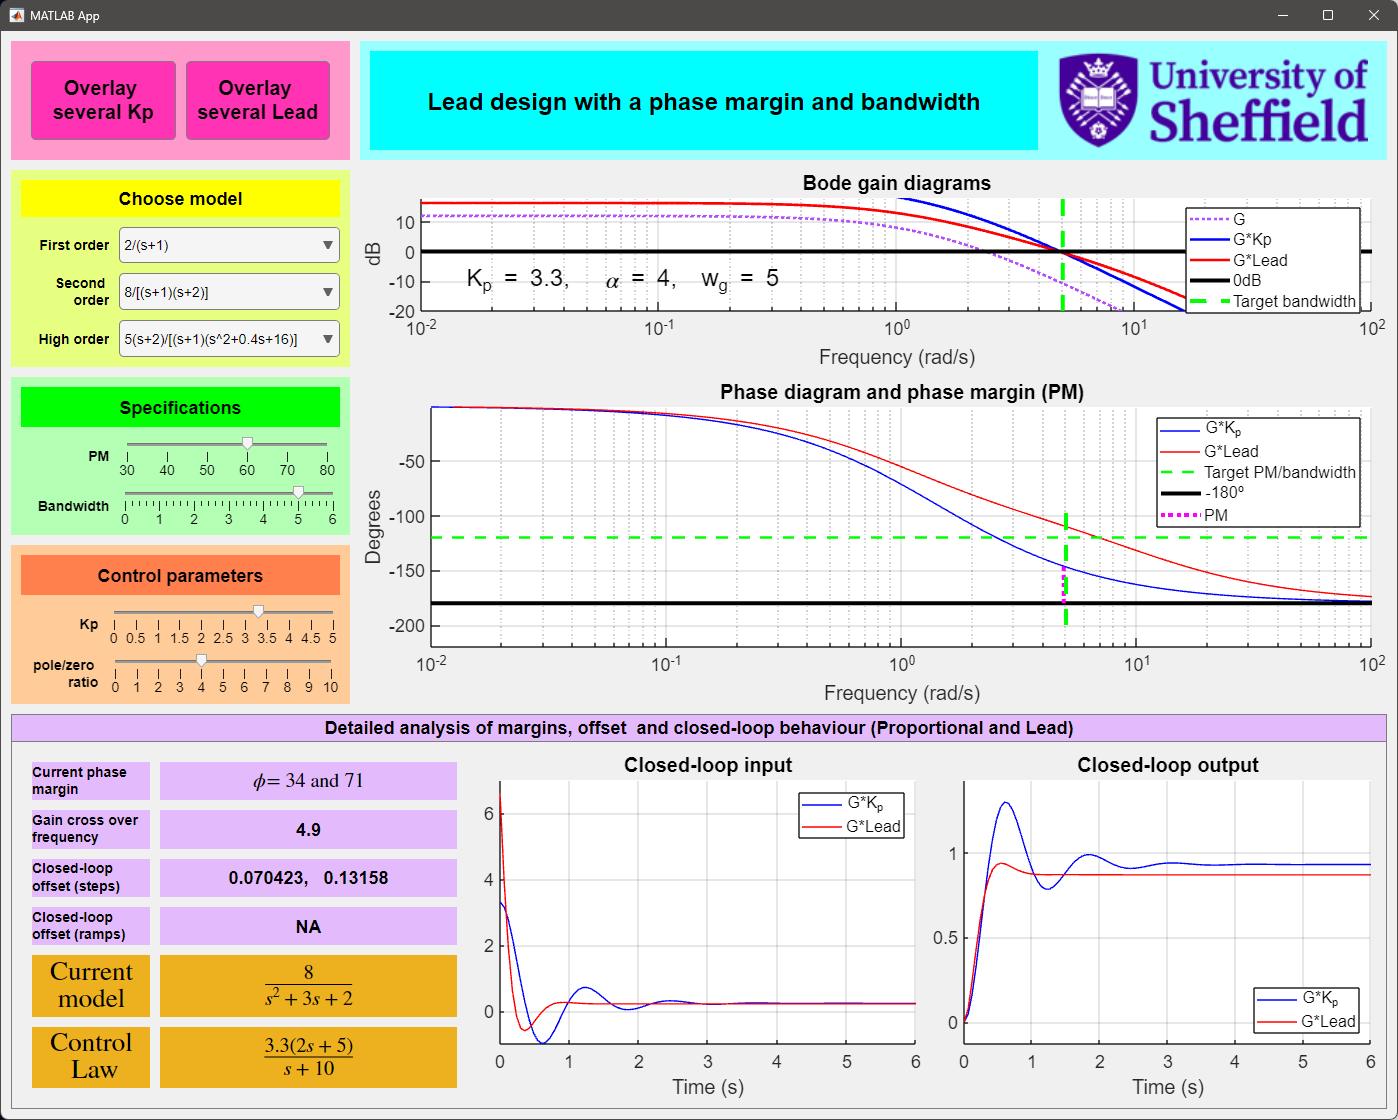

### 2.3 Remarks on Offsets

A lead does not deal with low frequency gain criteria explicity and thus one must accept what ever arises (or add a lag component in a lead-lag design). The formula required to determine the offsets are standard. The values are given in the text boxes in the bottom left for completeness.

**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$.  For the given lead, $M\left(0\right)=\frac{K_p }{\sqrt{\alpha }}$ .

**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)}$

## 3. The design and operation of the app

### 3.1 Basic operation

The user can interact using the sliders and buttons in the top left. The figures update whenever any value is changed.

- Use the sliders in the yellow box to select the desired system. The current choice is displayed in the orange box in the bottom left.

- Use the sliders in the green box to select the desired phase margin (PM) and bandwidth. These are shown in the figures using the dashed green lines.

- Use the sliders in the orange box to select the parameters ***Kp*** and $\alpha$ which define the Lead compensator. The corresponding  cross-over frequency $w_c$ used to define the lead is taken automatically from the green box slider (and thus may not correspond to the actual cross over frequency - it is assumed that the user manually ensures the two are the same by choosing ***Kp ***correctly).

The figures in section 2 show this basic operation of the app. From these values the proportional compensation and lead compensation are full defined and figures are produced.

- The top figure is the Bode diagram, with both the compensated and the uncompensated system.

- The actual PM is shown with the vertical pink dots. The desired PM and bandwidth is marked with the green dashed line. Ideally the vertical pink and green lines overlay.

- The closed-loop step response is shown in the bottom two figures (input and output).

- Core values such as offsets, margins (proportional and lag compensation respectively) are shown in the text boxes in the bottom left.

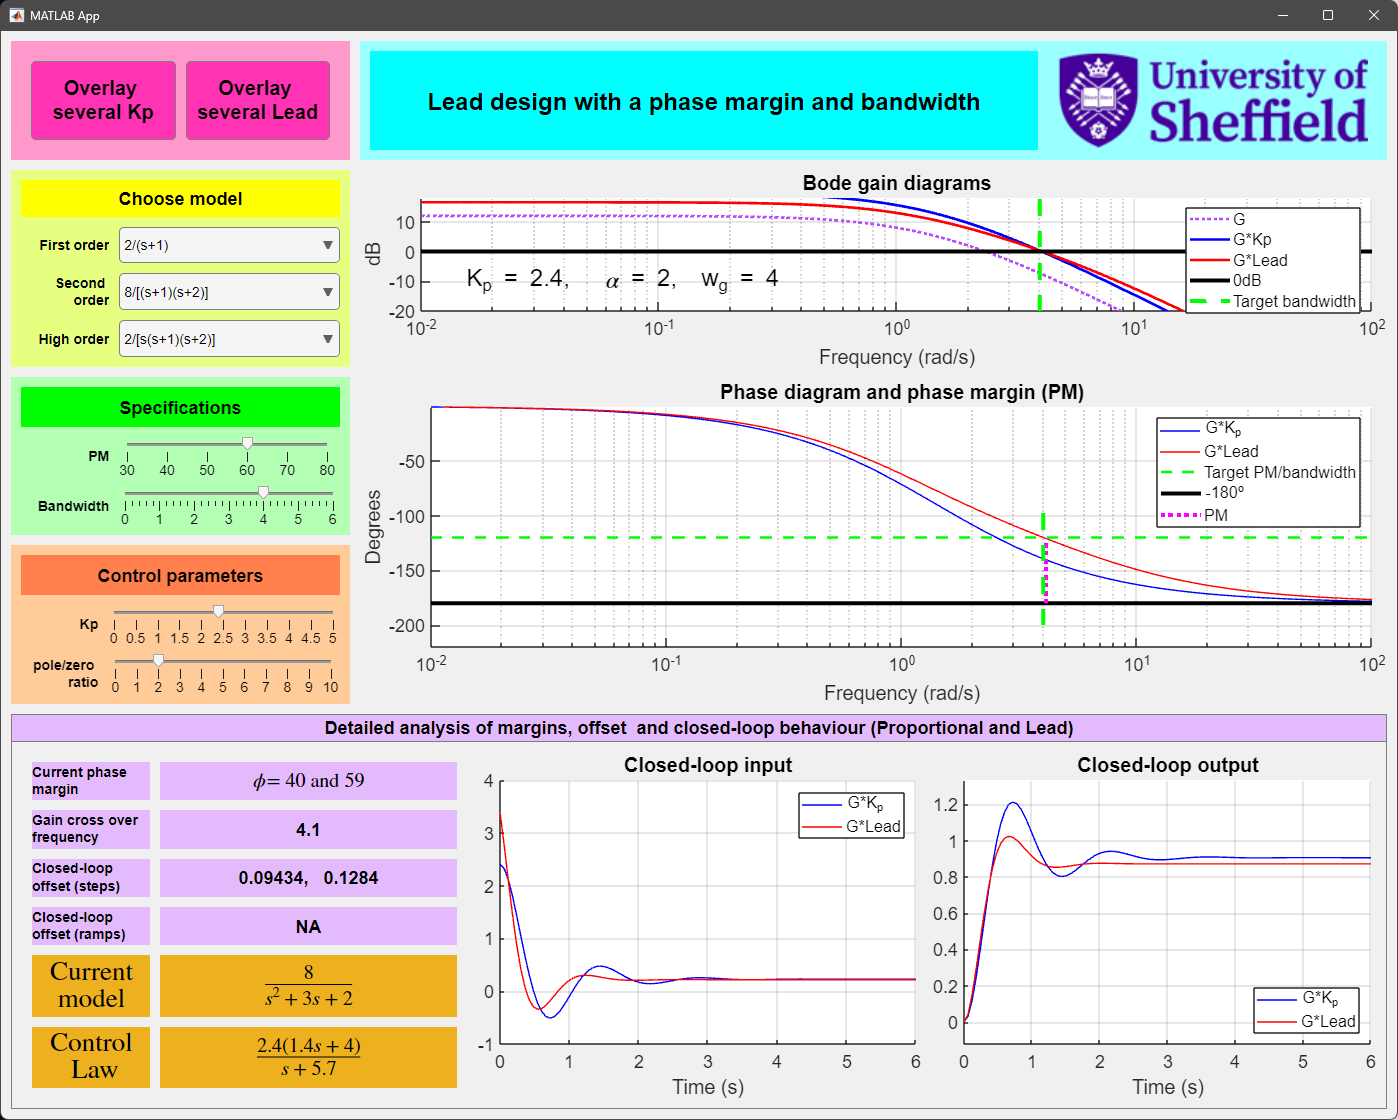

The user can attempt to meet specifications that they set (using green sliders) for a given system by making appropriate choices in the orange sliders. They can also observe clearly the differences between lead compensation and simple gain (proportional) design.

### 3.2 Overlay with alternative choices of proportional gain and/or lag pole/zero ratio

In order to support understanding of the two core design steps, the pink buttons give insight into each of these. As soon as you select any other button, the plots revert to the original single choice of compensator shown above.

Step 1 requires the choice of ***Kp. *** The pink button in the top left will replace all the plots with overlays with different choices so that one can quickly identify from the Bode gain plot roughly what value will give the desired cross over frequency. In essence which gain line crosses zero dB where the dotted green line crosses.

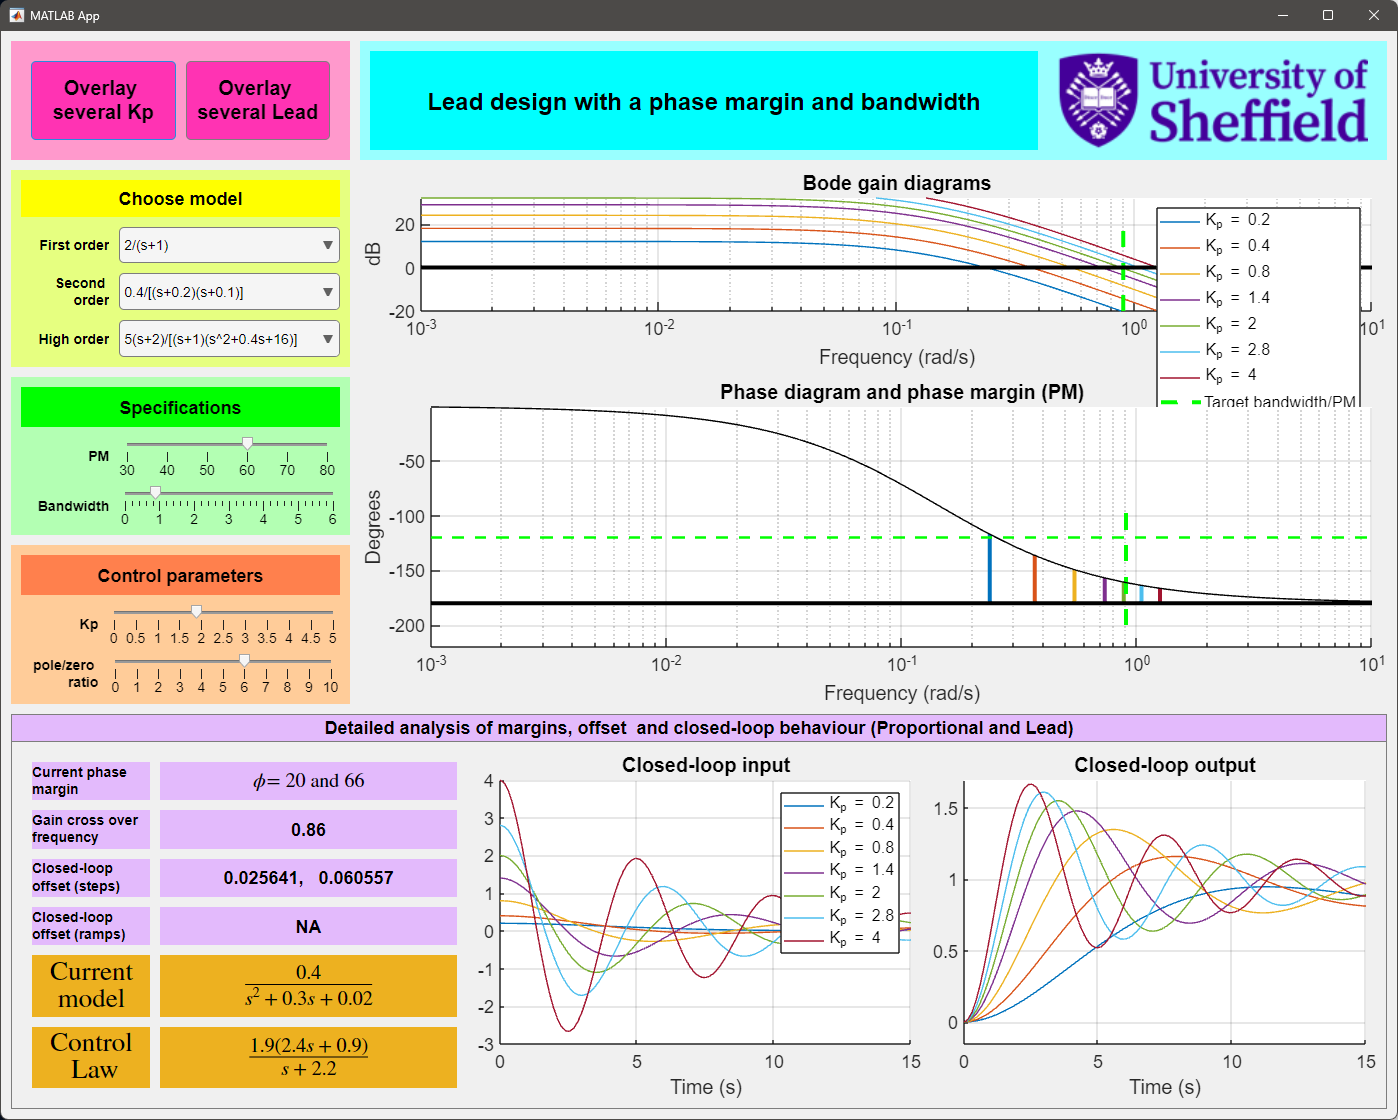

Step  2 focuses on the pole/zero ratio, once ***Kp*** is known. The right button in  the top left will overlay multiple lead compensators with different values of $\alpha$. Here it is clear from the gain plot that the gain cross-over frequency does not change, however from the phase plot one can see that different PM will result. Choose the value $\alpha$ which leads to  the desired PM.